# Platform path finding using RRT

## 2D grid

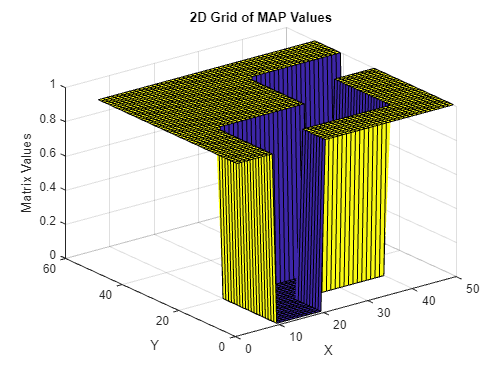

grid = ones(50,50);

% Obstacles
grid(10:20,1:20) = 0;
grid(20:40, 10:20) = 0;
grid(30:40, 20:40) = 0;
grid(40:50, 30:40) = 0;

% Create a 2D grid using meshgrid
[X, Y] = meshgrid(1:50, 1:50);

% Plot the 2D grid with the matrix values
% figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')
hold on

## Path

goal_node = [45,35];
start_node = [15,5];

% Plot the 2D grid with the matrix values
figure
surf(Y, X, grid)
xlabel('X')
ylabel('Y')
zlabel('Matrix Values')
title('2D Grid of MAP Values')
hold on 

[rrt_path, tree] = RRT2D(grid, start_node, goal_node);

    "PATH FOUND. Nodes num.: 37 Time: 0.0061969"



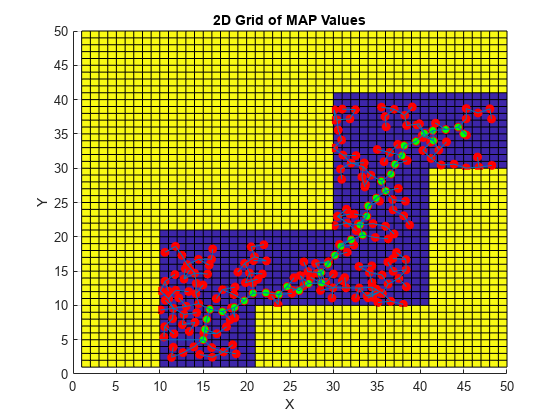

scatter3(tree(:,2), tree(:,3), zeros(size(tree(:,1))), 'MarkerFaceColor', 'red', 'MarkerEdgeColor', 'red');
hold on
scatter3(rrt_path(:,1), rrt_path(:,2), zeros(size(rrt_path(:,1))), 'MarkerFaceColor', 'green', 'MarkerEdgeColor', 'red');
for i = 1:1:length(tree)
    if tree(i,1) > 0
        line([tree(i,2), tree(tree(i,1),2)], [tree(i,3), tree(tree(i,1),3)], [0, 0]);
    else
        line([tree(i,2), tree(1,3)], [tree(i,3), tree(1,3)], [0, 0]);
    end
end
view([-0.167 90.000])